clearvars
data = normalize(readtable('dat.csv','NumHeaderLines',4))  % skips the first three rows of data

data = 63727×2 table
     Var1       Var2  
    _______    _______

     -1.732    0.12766
     -1.732    0.12992
    -1.7319    0.13235
    -1.7318    0.13493
    -1.7318    0.13783
    -1.7317    0.14074
    -1.7317    0.14381
    -1.7316    0.14719
    -1.7316    0.15075
    -1.7315    0.15446
    -1.7315    0.15817
    -1.7314     0.1614
    -1.7314     0.1643
    -1.7313    0.16656
    -1.7312    0.16866
    -1.7312    0.17092


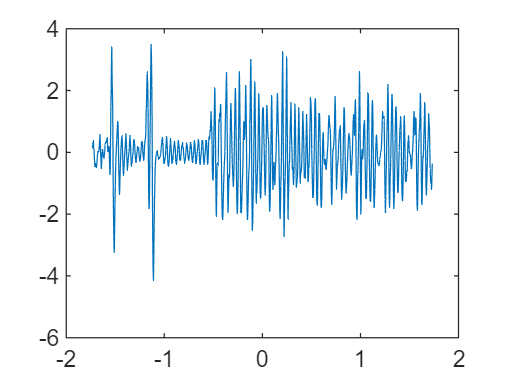

plot(data.Var1,data.Var2)

numObservations = length(data.Var1);
idxTrain = 1:floor(0.9*numObservations);
idxTest = floor(0.9*numObservations)+1:numObservations;
dataTrain = data(idxTrain,1);
dataTest = data(idxTest,1);

for n = 1:numel(dataTrain)
    X = dataTrain{n};
    XTrain{n} = X(:,1:end-1);
    TTrain{n} = X(:,2:end);
end

Subscripting into a table using one subscript (as in t(i)) is not supported. Specify a row subscript and a variable
subscript, as in t(rows,vars). To select variables, use t(:,i) or for one variable t.(i). To select rows, use t(i,:).